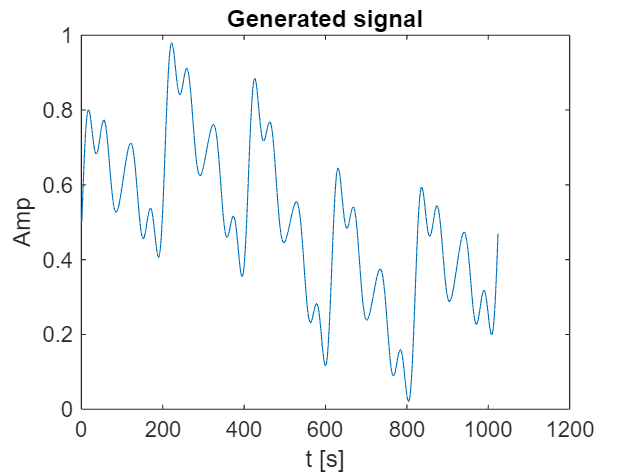

clear all
close all

% Generating multisine
f_i = [1,5,10,20,25];
U_i = [0.5,0.4,0.3,0.2,0.1];

N = 16;

dt = 1/1024;
t = [0:dt:1/f_i(1)-dt];

y_temp = 0;
for i = 1:length(f_i)
    y_temp = y_temp + U_i(i)*sin(2*pi*f_i(i)*t);
end

y = y_temp/(max(y_temp)-min(y_temp)+0.1)+0.5;
plot(y)
title('Generated signal')
xlabel('t [s]')
ylabel('Amp')

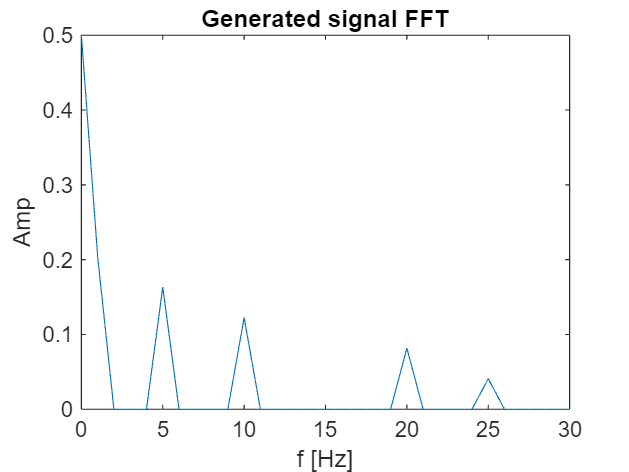

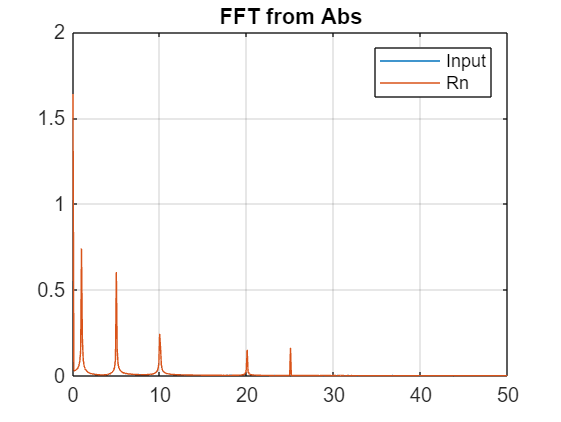

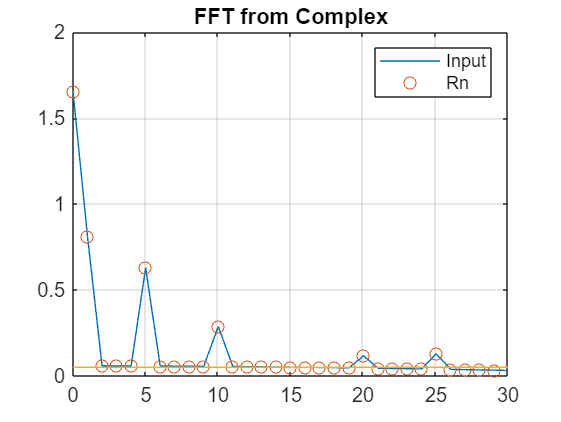

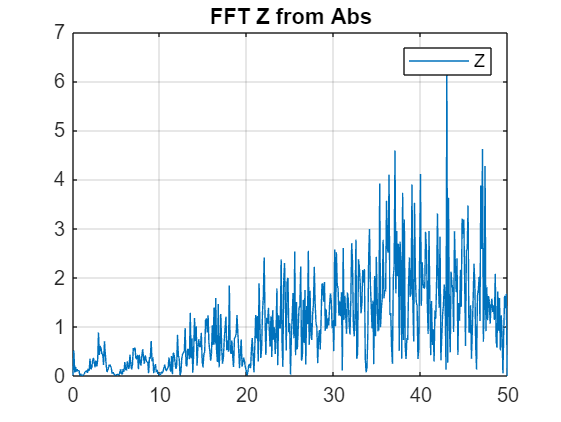

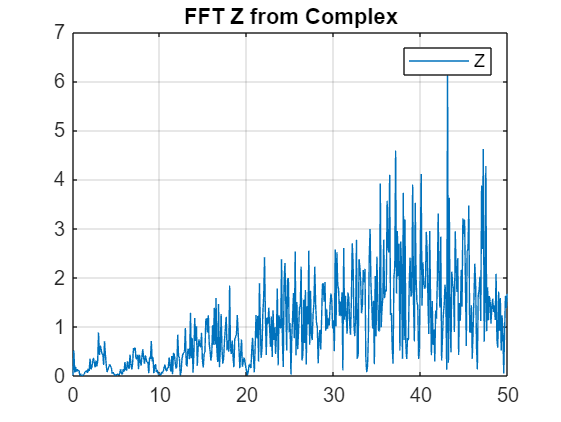

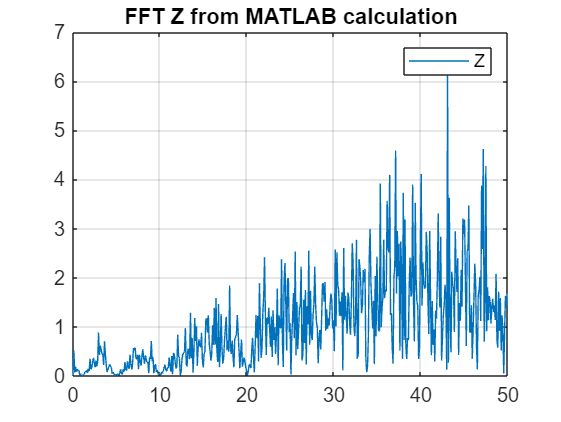


y_hex = floor(y*(2^N-1));
%scatter(t,y_hex);

hex_sine = dec2hex(y_hex);
MSB = bitshift(y_hex,-8);
msb_sine = "0x"+string(dec2hex(MSB));
lsb_sine = "0x"+string(dec2hex(y_hex-MSB*2^8));

mcu_sin = [msb_sine,lsb_sine];
mcu_sin_reshaped = reshape(mcu_sin',1,[]);

%writing to file for MCU
folder = "C:\Users\Peter\STM32CubeIDE\workspace_1.12.0\RedPill_DAC_SPI_MultiSin_FFT\Core\Src\";
fid = fopen(folder+"dacMultiSine.txt",'wt');
fprintf(fid,'%s,', mcu_sin_reshaped{1:end-1});
fprintf(fid,'%s', mcu_sin_reshaped{end});
fclose(fid);

% Spectre of generated signal
Y = abs(fft(y))/length(t);
df = (1/(length(t)*dt));
f = [0:df:(1/dt)-df];
f_egy = f(1:end/2);
Y(2:end) = 2*Y(2:end);
Y_egy = Y(1:end/2);
plot(f_egy,Y_egy)
xlim([0,30])
title('Generated signal FFT')
xlabel('f [Hz]')
ylabel('Amp')